clc
clf
clear all
close all
rng(0)

# Reinforcement learning fine-tuning

Tf = 3;
fs_ce = 600;     % Energy control frequency
Ts_ce = 1/fs_ce; % Energy control timestep

Xmax = load("ImitationLearningSimulink\TrainingData\Data\Xmax.mat").Xmax;
Ymax = load("ImitationLearningSimulink\TrainingData\Data\Ymax.mat").Ymax;

## Load environement

Open class template for reinforcement learning environement

mdl = "Simulate";
open_system(mdl)
agentblk = mdl + "/NN CEC/RL Agent";

obsInfo = rlNumericSpec([13 1], ...
          LowerLimit=-ones(13,1), ...
          UpperLimit=ones(13,1), ...
          Name='obs');

actInfo = rlNumericSpec([3 1], ...
    LowerLimit=-ones(3, 1), ...
    UpperLimit=ones(3, 1), ...
    Name='act');

env = rlSimulinkEnv(mdl, agentblk, obsInfo, actInfo, 'UseFastRestart', 'off');

## Critic

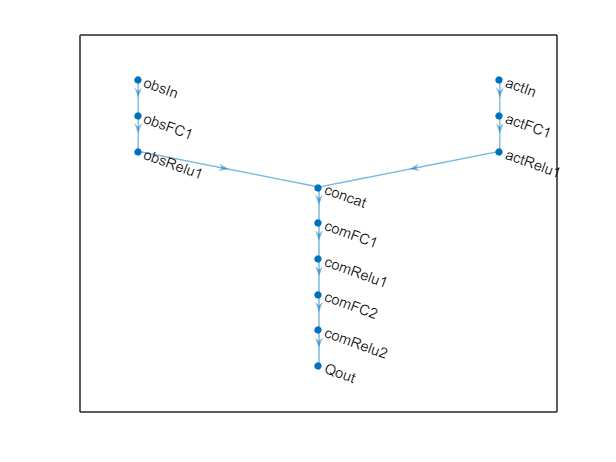

% Observation path
obsPath = [
    featureInputLayer(prod(obsInfo.Dimension), Name="obsIn")
    fullyConnectedLayer(128, Name="obsFC1", ...
        WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="obsRelu1")
];

% Action path
actPath = [
    featureInputLayer(prod(actInfo.Dimension), Name="actIn")
    fullyConnectedLayer(64, Name="actFC1", ...
        WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="actRelu1")
];

% Common path
commonPath = [
    concatenationLayer(1,2,Name="concat")             % [obs; act]
    fullyConnectedLayer(128, Name="comFC1", WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="comRelu1")
    fullyConnectedLayer(128, Name="comFC2", WeightsInitializer="narrow-normal", BiasInitializer="narrow-normal")
    reluLayer(Name="comRelu2")
    fullyConnectedLayer(1, Name="Qout", WeightsInitializer="narrow-normal", Bias=0, BiasLearnRateFactor=0)
];

% Create critic network
criticNet = dlnetwork;
criticNet = addLayers(criticNet, obsPath);
criticNet = addLayers(criticNet, actPath);
criticNet = addLayers(criticNet, commonPath);
criticNet = connectLayers(criticNet, "obsRelu1", "concat/in1");
criticNet = connectLayers(criticNet, "actRelu1", "concat/in2");

figure
plot(criticNet)


criticNet = initialize(criticNet);

% Create RL critic
critic = rlQValueFunction(criticNet, obsInfo, actInfo, ObservationInputNames="obsIn", ActionInputNames="actIn");

getValue(critic, {rand(obsInfo.Dimension)}, {rand(actInfo.Dimension)})

ans = single
-3.2398e-04

## Actor

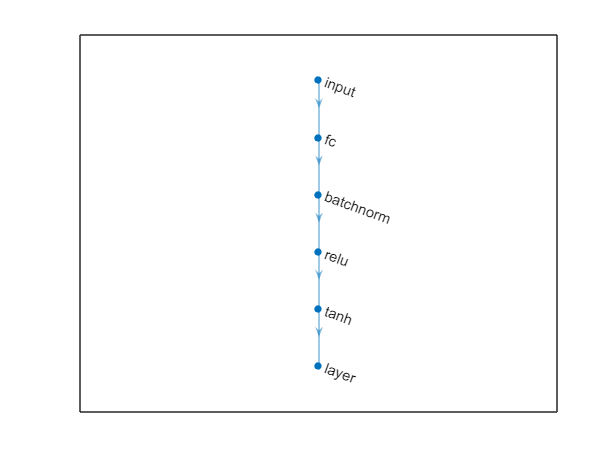

actorNet = load('ImitationLearningSimulink\ActualArchitecture\net.mat').net;

actorNet = dlupdate(@double, actorNet);

figure
plot(actorNet)

actorNet = initialize(actorNet);
summary(actorNet)

   Initialized: true
   Number of learnables: 1.2k
   Inputs:
      1   'input'   13 features


actor = rlContinuousDeterministicActor(actorNet, obsInfo, actInfo, ObservationInputNames="input");
cell2mat(getAction(actor, {rand(obsInfo.Dimension)}))

ans = 3×1 single column vector
   -0.4751
    0.1380
    0.2031


## Agent

agent = rlDDPGAgent(actor, critic);
agent.AgentOptions.SampleTime = Ts_ce;
agent.AgentOptions.DiscountFactor = 0.99;
agent.AgentOptions.NoiseOptions.Mean = 0;
agent.AgentOptions.NoiseOptions.StandardDeviation = 0.01;
agent.AgentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-5;
agent.AgentOptions.ExperienceBufferLength = 1e5;
agent.AgentOptions.MiniBatchSize = 64;
agent.AgentOptions.SequenceLength = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-4;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 5e-4;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.NumStepsToLookAhead = 1;
agent.AgentOptions.NumWarmStartSteps = agent.AgentOptions.MiniBatchSize;
agent.AgentOptions.NumEpoch = 1;
agent.AgentOptions.MaxMiniBatchPerEpoch = 100;
agent.AgentOptions.LearningFrequency = 100;
agent.AgentOptions.PolicyUpdateFrequency = 1;
agent.AgentOptions.TargetSmoothFactor = 1.0000e-03;
agent.AgentOptions.TargetUpdateFrequency = 1;
agent.AgentOptions.BatchDataRegularizerOptions = [];
agent.AgentOptions.ResetExperienceBufferBeforeTraining = 0;

agent

agent =   rlDDPGAgent with properties:

        ExperienceBuffer: [1×1 rl.replay.rlReplayMemory]
            AgentOptions: [1×1 rl.option.rlDDPGAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1×1 rl.util.rlNumericSpec]
              ActionInfo: [1×1 rl.util.rlNumericSpec]
              SampleTime: 0.0017

## Train

trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts_ce), ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    ScoreAveragingWindowLength=5,...
    StopTrainingValue=0);

doTraining = true;
if doTraining
    trainingStats = train(agent, env, trainOpts);
end
actual_agent = agent

actual_agent =   rlDDPGAgent with properties:

        ExperienceBuffer: [1×1 rl.replay.rlReplayMemory]
            AgentOptions: [1×1 rl.option.rlDDPGAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1×1 rl.util.rlNumericSpec]
              ActionInfo: [1×1 rl.util.rlNumericSpec]
              SampleTime: 0.0017